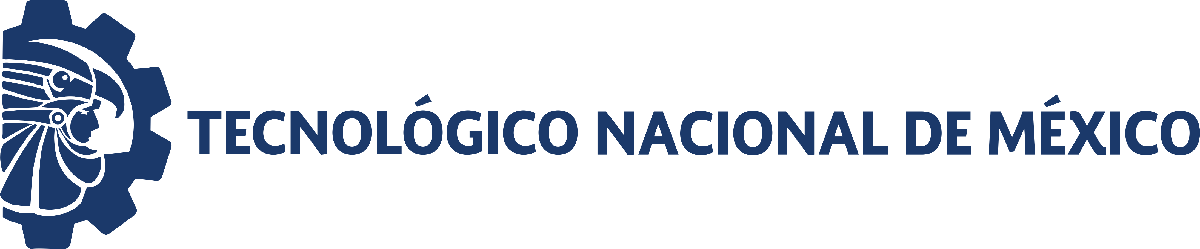                                 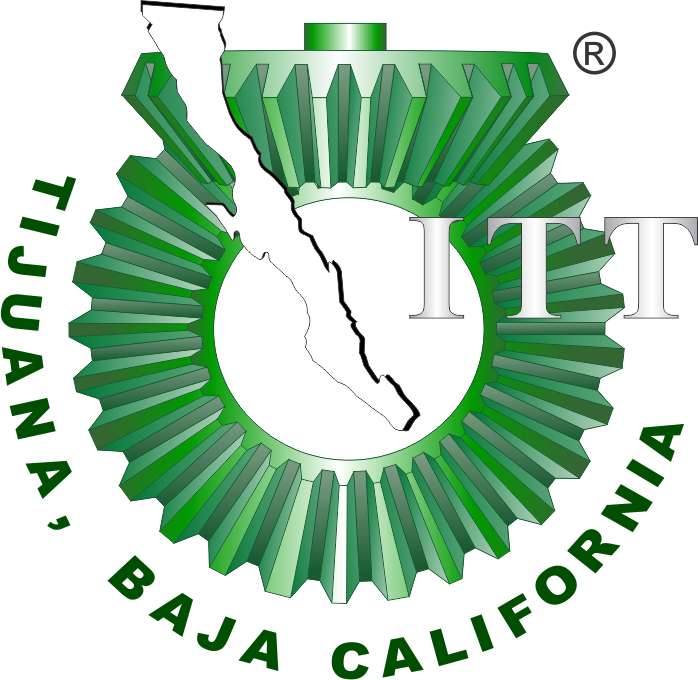

# Taller: Estimación de tasas de liberación de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica**

**Ingeniería Biomédica e Ingeniería Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# 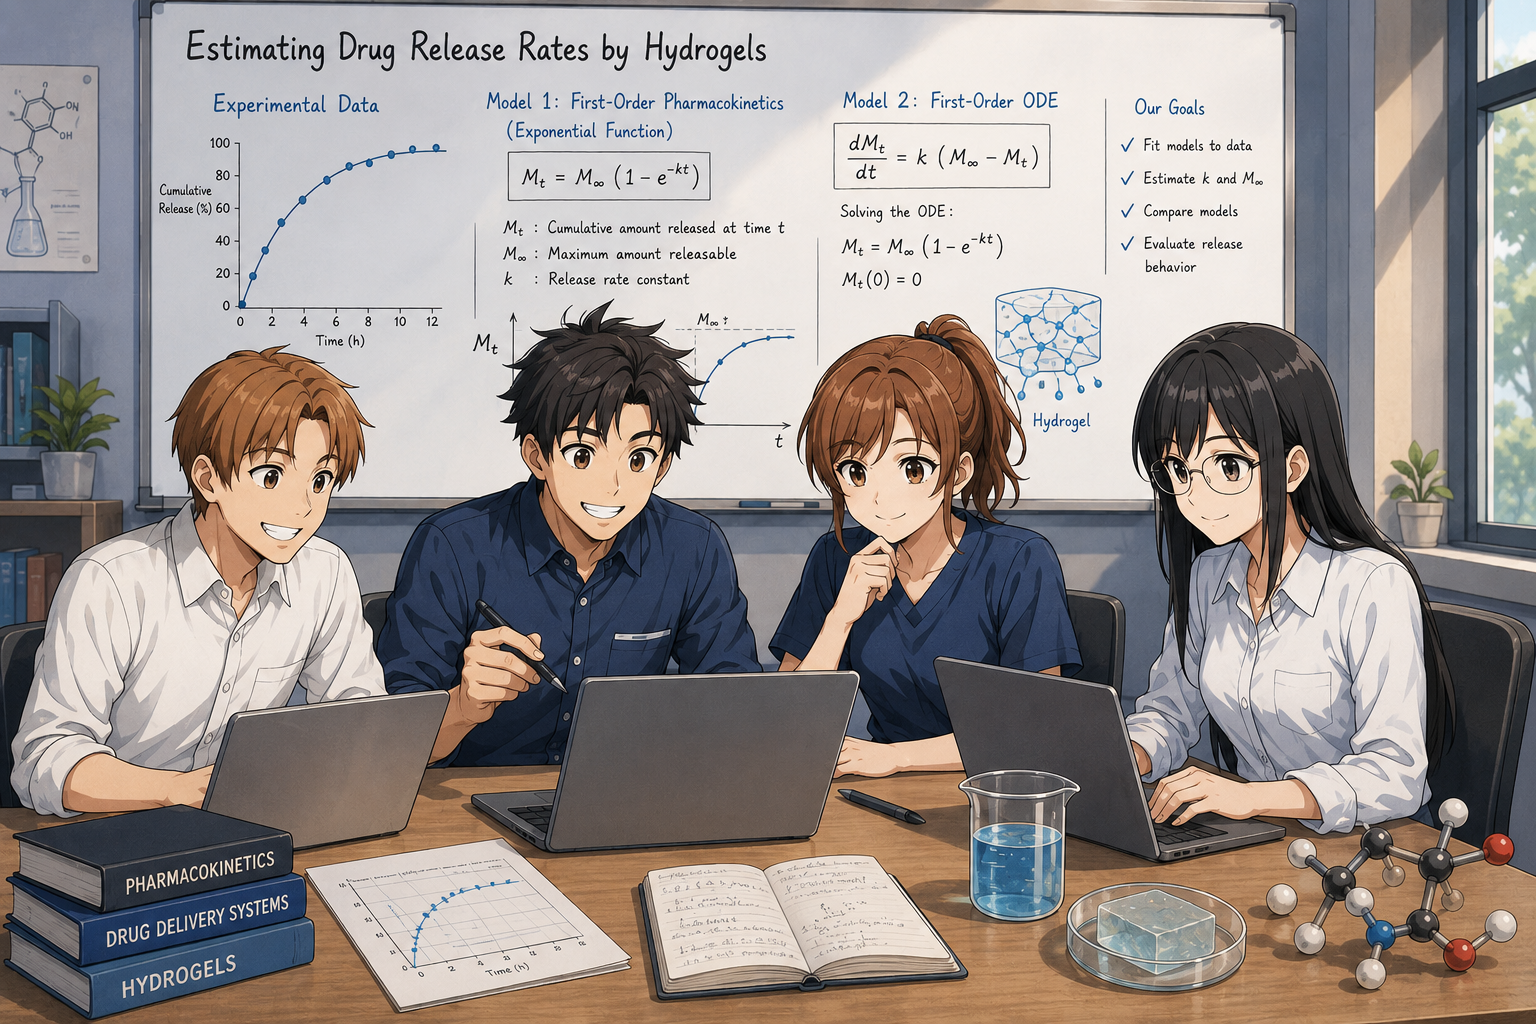

## Información del estudiante

[Foto otaku]

Nombre del alumno: **Nombres y Apellidos**

Número de control: **12345678**

Correo institucional: **xxx.xxx@tectijuana.edu.mx**

Carrea: **Ingeniería Biomédica/Electrónica**

Instructor: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36-2MBA3 con base en los datos experimentales de la siguiente figura.

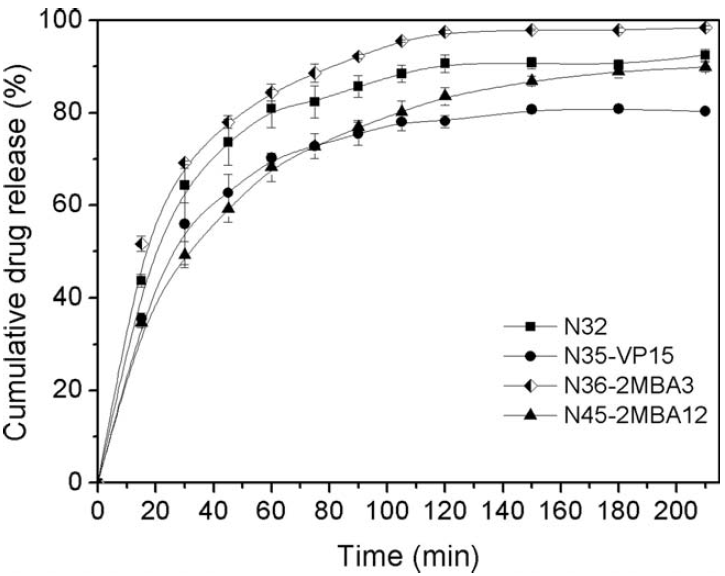          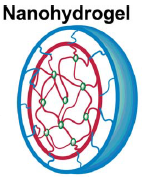

Un hidrogel es un material formado por redes tridimensionales de polímeros hidrófilos capaces de absorber y retener grandes cantidades de agua sin disolverse. Debido a su alta biocompatibilidad y similitud con tejidos biológicos, los hidrogeles son ampliamente utilizados en aplicaciones biomédicas como liberación controlada de fármacos, ingeniería de tejidos y sistemas de administración terapéutica.

La estimación de la tasa de liberación de un fármaco es importante porque permite comprender y predecir cómo el medicamento es liberado desde el hidrogel hacia el organismo a lo largo del tiempo. Esto ayuda a diseñar tratamientos más eficientes y seguros, optimizando la dosis, reduciendo efectos secundarios y garantizando concentraciones terapéuticas adecuadas durante periodos prolongados. Además, el modelado matemático de la liberación permite comparar formulaciones, ajustar parámetros cinéticos y desarrollar sistemas inteligentes de administración controlada de medicamentos.

## Referencias

[1] M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

[2] H. Motulsky, *Intuitive biostatistics: a nonmathematical guide to statistical thinking*. 4th ed. Oxford, New York, USA: Oxford University Press, 2014.

[3] Slavkova, K. P., Patel, S. H., Cacini, Z., Kazerouni, A. S., Gardner, A. L., Yankeelov, T. E., & Hormuth, D. A. (2023). Mathematical modelling of the dynamics of image-informed tumor habitats in a murine model of glioma. *Scientific reports*, *13*(1), 2916. DOI: [https://doi.org/10.1038/s41598-023-30010-6](https://doi.org/10.1038/s41598-023-30010-6)

[4] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

[5] Bryan, Kurt. *Differential equations: A toolbox for modeling the world*. Simiode, 2022. Permalink: [https://www.simiode.org/resources/8307](https://www.simiode.org/resources/8307) 

## Modelos a ajustar a los datos experimentales: Farmacocinética de primer orden

Ecuación diferencial ordinaria de primer orden: $$\dot x  = k(\beta -x)$ $

Función: $$x(t) = \beta(1 - e^{-kt})$ $

## Datos experimentales

## Regresión no lineal, bioestadísticos y experimentación in silico

### Regresión no lineal

La regresión no lineal se basa en el método de mínimos cuadrados, permite ajustar modelos complejos a conjuntos de datos experimentales con diversas variables dependientes e independientes, además de distintos parámetros que describen las relaciones entre ellas; funciona mediante un enfoque iterativo y se debe elegir una estimación inicial para el valor de cada parámetro.


$$\sum_{i=1}^n {\left\lbrack x_i -f\left(\hat{x_i } ,\rho \right)\right\rbrack }^2 ,$$


donde $x_i$ se refiere a los datos experimentales [xo] y $\hat{x_i }$ a los datos estimados por el modelo [xf], $n$ es la cantidad de datos observados y el arreglo $\rho$ contiene los parámetros a ajustar [$\beta$ y $k$].

### Modelo: $\dot{x} =k\left(\beta -x\right)$

### Solución de la EDO por separación de variables


$$\dot{x} =\frac{\textrm{dx}}{\textrm{dt}}=k\left(\beta -x\right)$$



$$\int \frac{\textrm{dx}}{\beta -x}=\int \textrm{kdt}$$



$$-\ln \left|\beta -x\right|+c_1 =\textrm{kt}+c_2$$



$$\ln \left|\beta -x\right|=-\textrm{kt}+c_3$$



$$\beta -x=e^{-\textrm{kt}+c_3 }$$



$$x\left(t\right)=\beta -{c_0 e}^{-\textrm{kt}}$$



$$x\left(0\right)=0$$



$$0=$$

$$\beta -{c_0 e}^{-k\left(0\right)}$$



$$c_0 =\beta$$



$$x\left(t\right)=$$

$$\beta \left(1-e^{-\textrm{kt}} \right)$$


### Modelo: $x\left(t\right)=\beta \left(1-e^{-\textrm{kt}} \right)$

## Funciones

### Gráficas

function plotdata(t,xo,xf,opt)

end

### Modelo: Ecuación diferencial ordinaria

Un sistema es un conjunto de "cosas" relacionadas entre sí, un sistema dinámico es aquel en el cual sus variables evolucionan a través del tiempo.


$$$\dot{x}=f\left( t,x\right) $$$


Métodos numéricos: Euler


$$$x_{i+1}=x_{i}+f\left(t, x_{i}\right) \Delta _{t}$$$


Métodos numéricos: Heun


$$$x_{i+1}=x_{i}+\frac{f\left(t, x_{i}\right) +f\left(t, x_{n}\right) }{2}\Delta_{t}$$$


function mdl = variant_1(to,xo,par)
    
    function xi = model(par,t)

    end

end

### Modelo: Función del tiempo

function mdl = variant_2(to,xo,par)
    
    function x = model(par,t)

    end
    
end

### Bioestadísticos

**H0 (hipótesis nula):** "El valor de cada parámetro del sistema es cero", es decir, no hay interacción entre las variables descritas por el término donde aparece dicho parámetro.

**Nivel de significación (**$\alpha$**):** Es el umbral de probabilidad utilizado para determinar si un resultado estadístico es significativo o no, este valor se debe establecer previamente en un estudio.

**Valor P:** Es la probabilidad de obtener un resultado igual o más extremo que el observado suponiendo que H0 es verdadera, un valor P bajo sugiere que la hipótesis nula es poco probable y que la hipótesis alternativa (H1) es más plausible. Si el valor P es lo suficientemente pequeño (menor que $$\alpha$), se considera que los resultados son estadísticamente significativos (es poco probable que se deban al azar).

**Grados de libertad (dof):** Son la cantidad de valores que se pueden variar en un conjunto de datos sin afectar la estimación de un parámetro estadístico, es decir, representan la cantidad de información que se utiliza para hacer una inferencia estadística.  En algoritmos de regresión, los grados de libertad se refieren al número de datos experimentales de la muestra menos el número de parámetros a estimar en el modelo.

**Error estándar (SE):** Es una medida que permite expresar la precisión en la estimación de un parámetro en modelos de regresión, cuanto más pequeño sea el error, más precisa será la estimación. En algoritmos de regresión, el SE se puede estimar desde los resultados de la matriz de covarianzas ($\Sigma$) al calcular la raíz cuadrada de los elementos de su diagonal principal, es decir, para un conjunto de parámetros estimados ($\rho_i$) se tiene que


$$\textrm{SE}\left(\rho_i \right)=\sqrt{{\Sigma \rho }_i }=\sqrt{\textrm{var}\left(\rho_i \right)}\ldotp$$


**Intervalos de confianza (CI):** Indican un rango de valores en el que se espera que esté el verdadero valor de un parámetro $$\rho_i$$ con un nivel de confianza predeterminado; este concepto se resume en la siguiente frase: **se tiene una confianza del 95% de que el intervalo contenga el verdadero valor del parámetro **$$\rho_i$$**.**


$$$CI_{95}\left( \rho _{i}\right) =\left( 
\begin{array}{ccc}
\rho _{i}-MoE & , & \rho _{i}+MoE%
\end{array}%
\right) $
$$



$$$MoE=SE\left( \rho _{i}\right) \times t^{\ast }$$$


donde $t^*$ es el valor crítico de t o valor de t de Student en la distribución, cuyo valor depende de $\alpha$ y los grados de libertad [[www.ttable.org](http://www.ttable.org)].

**El coeficiente de determinación o R cuadrada: **es una medida estadística cuantitativa utilizada para evaluar la bondad de ajuste en modelos de regresión y medir la proporción del total de la varianza de las variables dependientes que puede ser explicada por dicho modelo. Es importante mencionar que la R² no puede ser mayor a 1, pero sí se pueden obtener valores negativos.


$$R^2 =\frac{\textrm{RSS}}{\textrm{TSS}},$$


donde


$$\textrm{RSS}=\sum_{i=1}^n {\left(x_i -\hat{x_i } \right)}^2 ,$$


se denomina como el residuo de la suma de los cuadrados (RSS, residual sum of squares del inglés) con $x_i$ representando los datos experimentales y $\hat{x_i }$ los datos aproximados o ajustados (fitted values del inglés) por el algoritmo de regresión con el modelo matemático formulado. Los residuales son las discrepancias o errores denotados por las distancias verticales entre los datos experimentales y los aproximados. Adicionalmente,


$$\textrm{TSS}=\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 ,$$


establece el total de la suma de los cuadrados (TSS, total sum of squares del inglés) con $\bar{x}$ como el promedio de los datos experimentales.

**Criterio de información de Akaike (AIC):** Es un método utilizado para la comparación y selección de modelos en el análisis estadístico, fue propuesto para comparar diferentes modelos y determinar cuál de ellos es el más adecuado; se basa en la cantidad de información que se pierde al ajustar un modelo a los datos experimentales, en general, un modelo más complejo con una mayor cantidad de parámetros puede ajustarse mejor a los datos, sin embargo, también puede sobreajustarse y tener un peor rendimiento o ajuste con nuevos datos.

Para muestras grandes (datos (n) / parámetros (K) >= 40):


$$\textrm{AIC}=n\;\ln \frac{\textrm{RSS}}{n}+2K\ldotp$$


Para muestras pequeñas (datos (n) / parámetros (K) < 40):


$$\textrm{AIC}=n\;\ln \frac{\textrm{RSS}}{n}+2K+\frac{2K\left(K+1\right)}{n-K-1}\ldotp$$


function biostats(mdl,Parameters)

end